%Load Pre-Trained VGG19
clc
clear
net = vgg19;
layers = net.Layers;

%Read Dataset and Knowing Categories
path = fullfile(pwd);
filepath = [path,filesep,'Gender Classification'];
imds = imageDatastore(filepath,...  
    'IncludeSubfolders',true,...
    'LabelSource','foldernames'); 
label_class = unique(imds.Labels)

label_class = 2×1 categorical array
     Female 
     Male 


Categories = length(label_class);

% A=imds.Files(1);
% B=imread(A{1,1})
% C=imresize(B,[227 227]);
% imshow(C)

% We look at the first layer to see the size requirement
sizeRequirement = net.Layers(1).InputSize;
inputSize = sizeRequirement(1:2)

inputSize =    224   224



% % Create anonymous function
imds.ReadFcn = @(img) imresize(imread(img),inputSize);

%Splitting Train, Test, and Validation Dataset
[trainDS, valDS, testDS] = splitEachLabel(imds,0.7,0.15,0.15,'randomized');

%layers

%Modifying pretrained model
numClasses = numel(unique(imds.Labels))

numClasses = 2

layers(end-2) = fullyConnectedLayer(numClasses,'Name',['fc' num2str(numClasses)]);
layers(end) = classificationLayer('Name','classOut');

newLayers = layers

newLayers =   47x1 Layer array with layers:

     1   'input'      Image Input             224x224x3 images with 'zerocenter' normalization
     2   'conv1_1'    Convolution             64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'    ReLU                    ReLU
     4   'conv1_2'    Convolution             64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'    ReLU                    ReLU
     6   'pool1'      Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'    Convolution             128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'    ReLU                    ReLU
     9   'conv2_2'    Convolution             128 3x3x128 convolutions with stride [1  1] and padding [1  1  1  1]
    10   'relu2_2'    ReLU                    ReLU
    11   'pool2'   

%Hyperparameter tuning
trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',0.001,...
    'ValidationData',valDS,...
    'Plots','training-progress',...
    'MiniBatchSize', 50,...
    'ValidationPatience', 3);

Initialization may take a minute before training begins


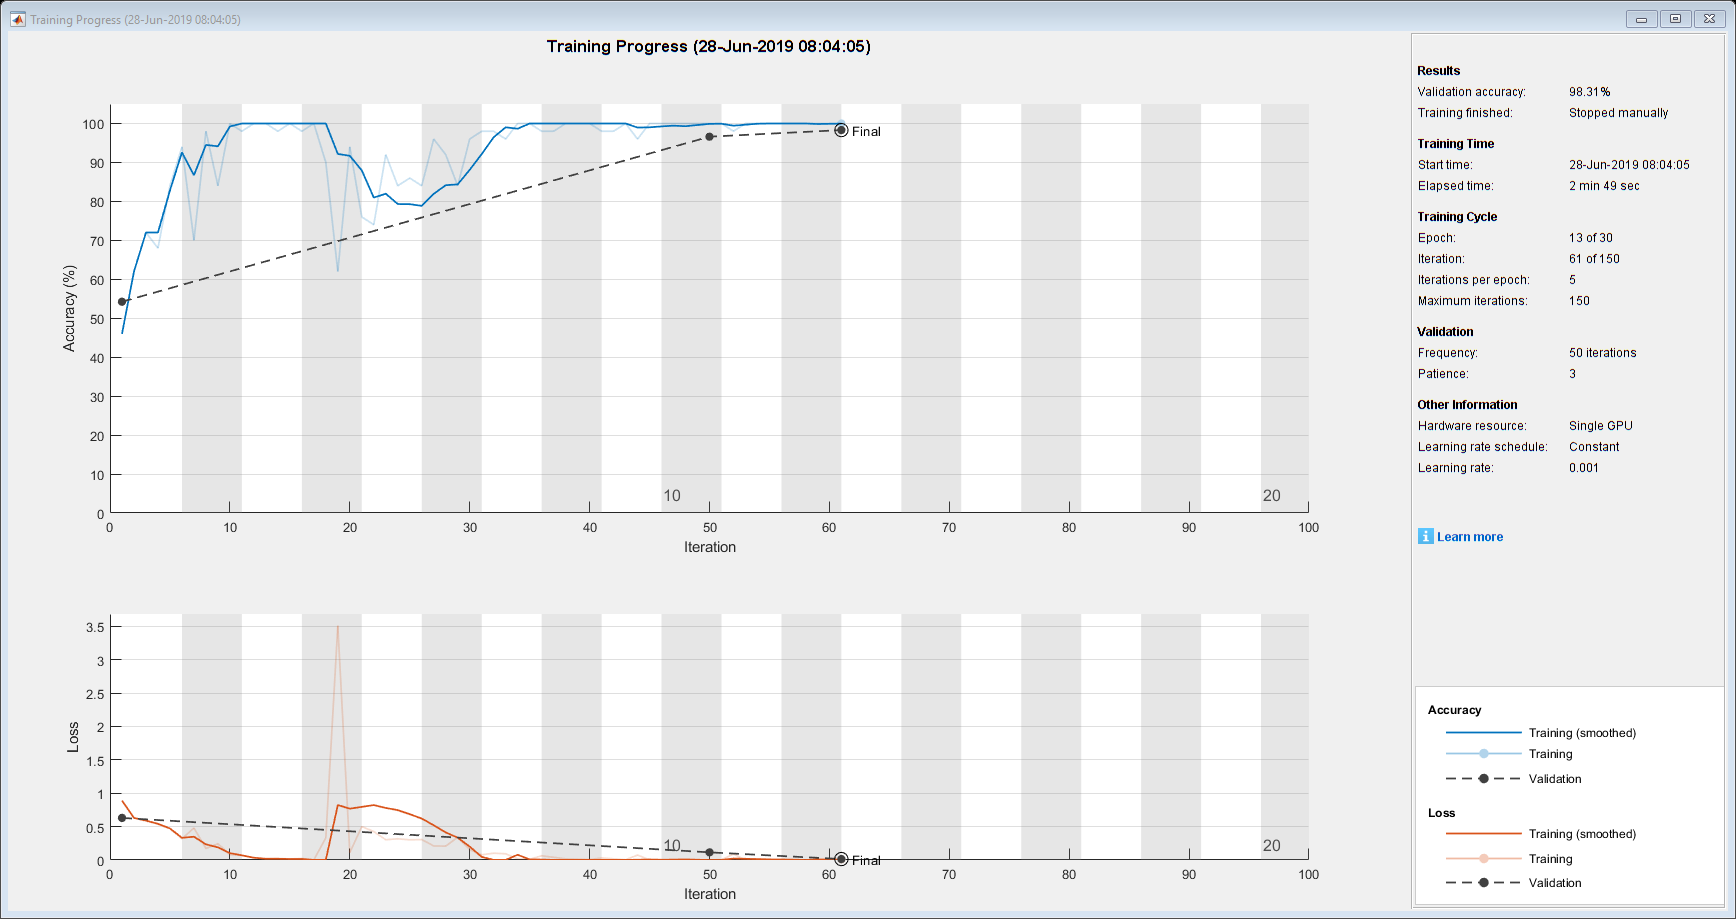

Training on single GPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       46.00% |       54.24% |       0.8897 |       0.6301 |          0.0010 |
|      10 |          50 |       00:02:18 |      100.00% |       96.61% |       0.0005 |       0.1146 |          0.0010 |
|      13 |          61 |       00:02:49 |      100.00% |              |       0.0093 |              |          0.0010 |
|======================================================================================================================

%Training the model
doTraining = true;

if doTraining
    disp('Initialization may take a minute before training begins');
    net_Face = trainNetwork(trainDS, newLayers, trainOpts);
end

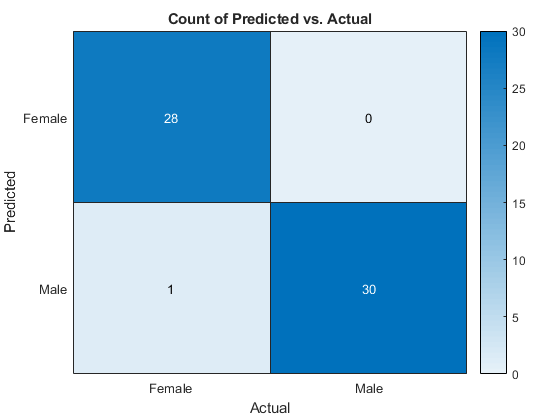

%Testing
doTest = true;

if doTest
    [labels, scores] = classify(net_Face, testDS);
else
    load testResults.mat 
end

% Calculate accuracy
accuracy = sum(labels == testDS.Labels)/numel(labels);

% Confusion Matrix - visual inspection of accuracy and error
tbl = table(labels,testDS.Labels,...
    'VariableNames', {'Predicted', 'Actual'});

figure('name','Confusion Matrix')
heatmap(tbl,'Actual','Predicted');


% Are there trends in the misclassifications?
% Where might these come from?

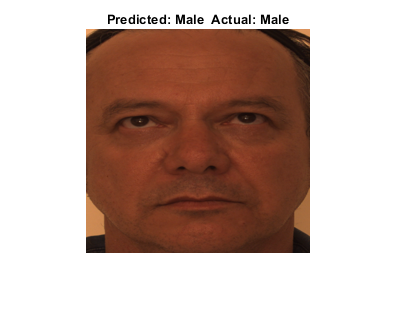


randNum = randi(length(testDS.Files));
imOriginal = readimage(testDS,randNum);
imResized = imresize(imOriginal, inputSize);

actualLabel = testDS.Labels(randNum);
predictedLabel = classify(net_Face,imResized);
imshow(imOriginal)
title(['Predicted: ' char(predictedLabel) '  Actual: ' char(actualLabel)],'Interpreter','none')

a='sahil.jpg';
imOriginal = imread(a);
imResized = imresize(imOriginal, inputSize);
actualLabel = 'Male';
predictedLabel = classify(net_Face,imResized);
imshow(imOriginal)

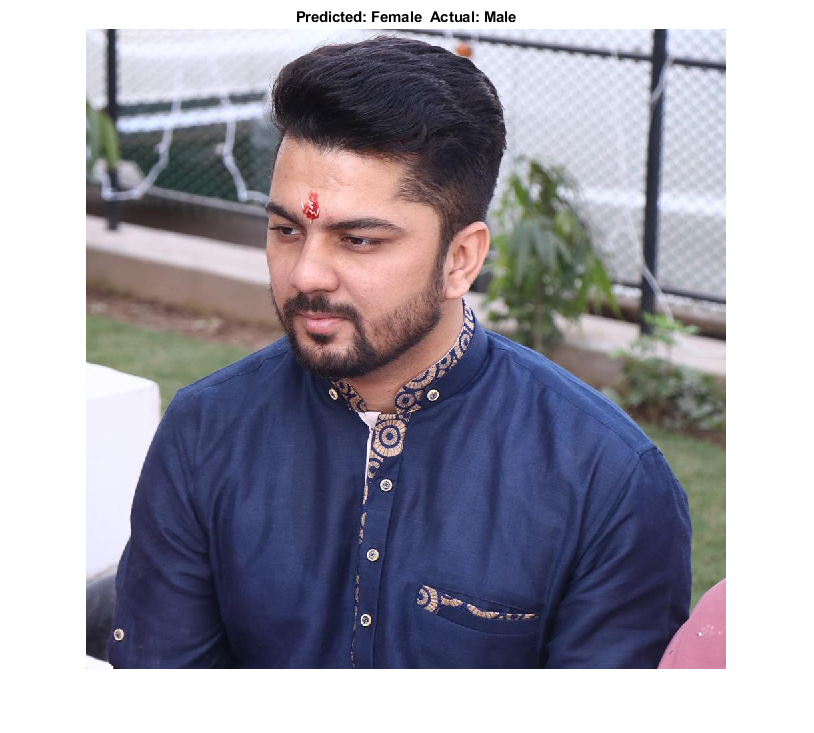

title(['Predicted: ' char(predictedLabel) '  Actual: ' char(actualLabel)],'Interpreter','none')